# *k*-Means Clustering

En esta lectura se realizará clustering con k-means en un conjunto de datos tridimensionales. En el proceso, se determinará el número correcto de clusters utilizando las funciones silhouette y evalclusters. 

Al realizar el clustering con k-means, se pueden seguir estas recomendaciones:

- Usar la opción "Replicates" para buscar la solución con la menor suma total de distancias

- Compare las soluciones de clustering de k-means para diferentes valores de k para determinar un número óptimo de clusters para sus datos.

- Evalúe las soluciones de clustering examinando los gráficos de silueta y los valores de silueta.

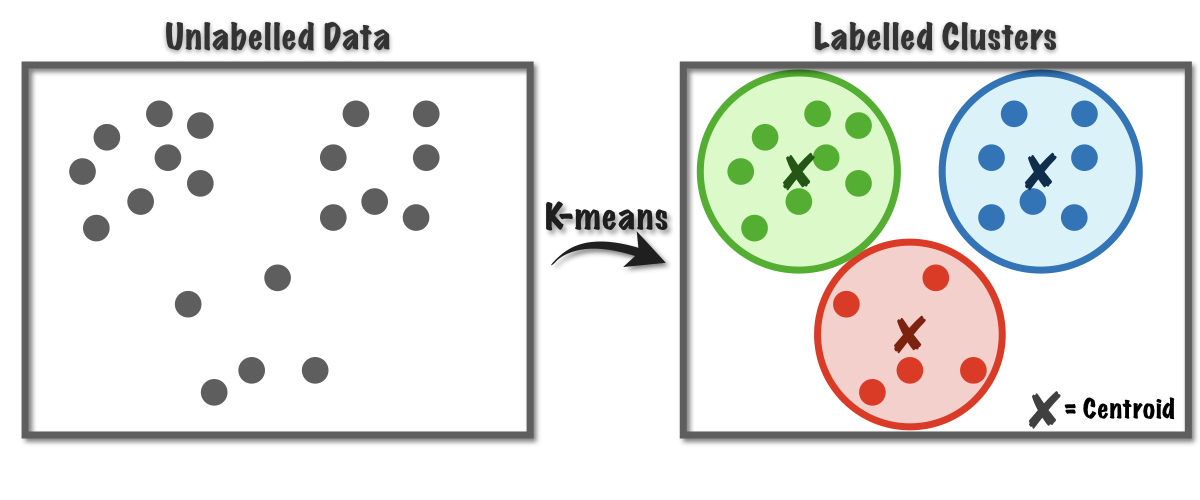

El algoritmo de K-means consiste en los siquientes pasos:

- Se determina el número de clusters K

- Se inician los centroides al azar y se calcula la distancia de cada punto respecto a estos centros

- Se determina pertenencia de acuerdo al más cercano

- Se determinan nuevamente los centros de acuerdo a la expresión

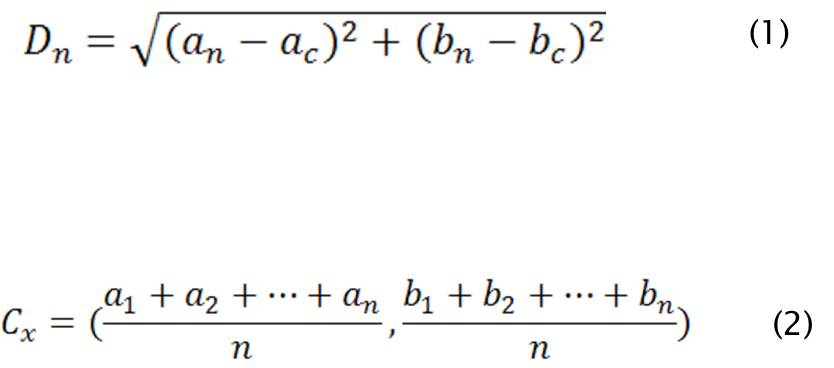

## Cargamos datos

Usamos como ejemplo el dataset `kmeansdata`

load("kmeansdata.mat")

% Tomamos solo las primeras 3 dimensiones
X = X(:,1:3);

## Visualizamos datos

Cuando sea posible, visualizar datos ayuda a decidir los pasos a seguir, así como interpretar la información entregada por los clusters

Podemos usar la función [stackedplot](https://www.mathworks.com/help/matlab/ref/stackedplot.html) para graficar cada característica o variable.

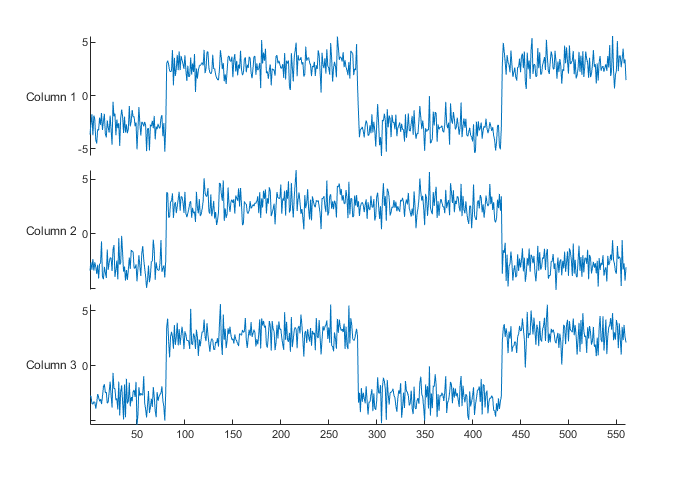

stackedplot(X);

Cada columna de la variable X es un gráfico

## **Creamos los clusters**

La función `kmeans` realizará el proceso. Iniciando con $k=2$ y usando `dist = squeclidean`. El número de clusters y tipo de distancia pueden variarse para cambiar los resultados.

- How many clusters would you create based on all the information you see here?

- What distance metric(s) would you choose for this data?

Because `kmeans` uses random starting points, the `"Replicates"` name-value pair is included to help find the best solution by running the clustering algorithm the indicated number of times. The result with the lowest total sum of distances is returned.

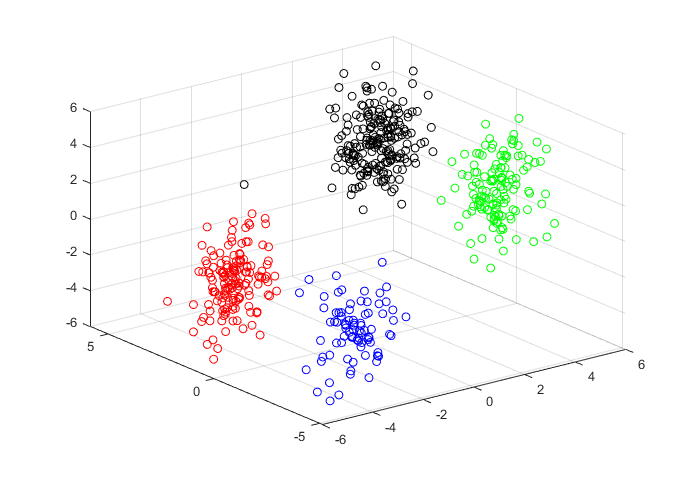

k=4; % número de clusters
idx = kmeans(X,k,"Distance","sqeuclidean","Replicates",5);
c = [0 0 0; 1 0 0; 0 1 0; 0 0 1; 0 1 1]; % colores para representar los grupos
scatter3(X(:,1),X(:,2),X(:,3),[],c(idx,:))

## Evaluando clusters con gráficas de silueta

Al observar los datos en 3 dimensiones es claro que deben ser 4 clusters. ¿como evaluar en casos que no sea obvio? ¿Como determinar el número de clusters?

Los gráficos de silueta miden que tan similar es un punto respecto a otros en el mismo cluster o grupo, es importante tomar en cuenta que los datos estan normalizados con rango de -1 a 1 para que cada dimensión o variable  tenga la misma importancia.

Un valor positivo cercano a 1 indica buen match del punto con ese cluster y un nivel bajo respecto a los otros clusters. Un valor cercano a -1 indica una probable asignación erronea de cluster

Ejecute el código varias veces para observar las diferencias

### 5 Clusters

Para comenzar, se asignarán 5 clusters, $k=5$. Ambas funciones, `kmeans` y `silhouette `deben usarla misma distancia

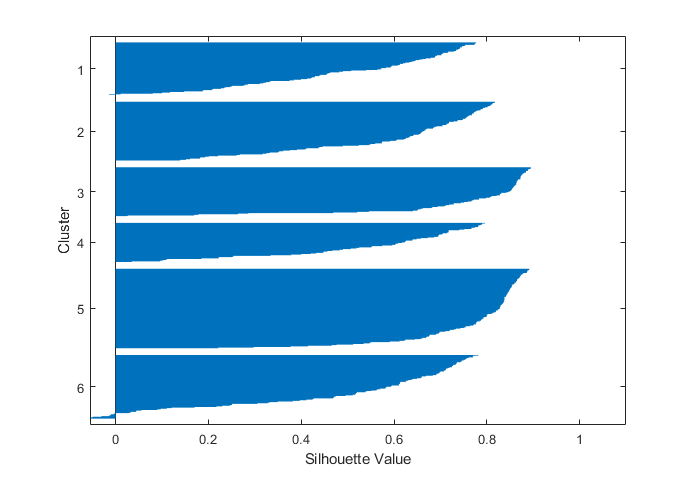

idx5 = kmeans(X,6,"Distance","sqeuclidean","Replicates",5);
[silh5,h] = silhouette(X,idx5,"sqEuclidean");
xlabel("Silhouette Value")
ylabel("Cluster")

El gráfico muestra un par de clusters con valores bajos. Esto indica que ambos clusters no esta separados lo suficiente

De manera mas cuantitativa puede obtenerse el valor promedio para los valores de siluetas

s5 = mean(silh5)

s5 = 0.6263

### 4 Clusters

Reducimos numero de clusters $k=4$.

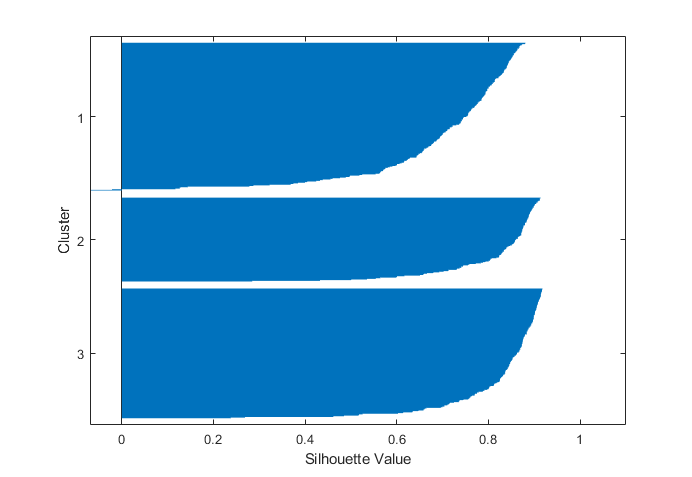

[idx4,C,sumd] = kmeans(X,3,"Distance","sqeuclidean","Replicates",5);
[silh4,h] = silhouette(X,idx4,"sqEuclidean");
xlabel("Silhouette Value")
ylabel("Cluster")

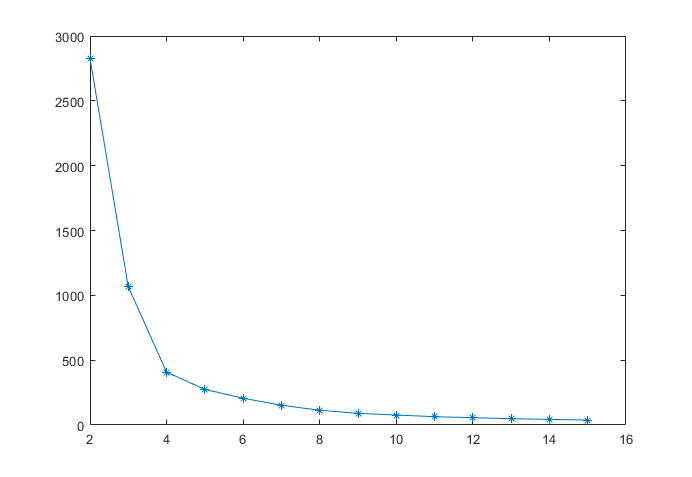

vector_k=nan(1,15);
for k=2:1:15
    [idx4,C,sumd] = kmeans(X,k,"Distance","sqeuclidean","Replicates",5);
    vector_k(k)=mean(sumd);
end
plot(vector_k,"Marker","*")

Ya no se presentan valores negativos en las siluetas, esto indica que el proceso ha mejorado 

s4 = mean(silh4)

s4 = 0.7761

## evaluando multiples valores para `k` con la función `evalclusters`

El objetivo es asignar un rango de clusters a evaluar, obtener el valor promedio de siluetas y así decidir el valor K que genere el valor mas alto para ese conjunto de datos

En el ejemplo el rango será de 2 a 6

clustev = evalclusters(X,"kmeans","silhouette","KList",2:6)

clustev =   SilhouetteEvaluation with properties:

    NumObservations: 560
         InspectedK: [2 3 4 5 6]
    CriterionValues: [0.7563 0.7761 0.8200 0.7605 0.6303]
           OptimalK: 4


La propiedad OptimalK nos entrega el valor K que genera el máximo valor de silueta promedio

kbest = clustev.OptimalK

kbest = 4

## Ejercicios de práctica

Ahora usemos el dataset completo con 4 dimensiones

- ¿Cual es el número de clusters óptimo?

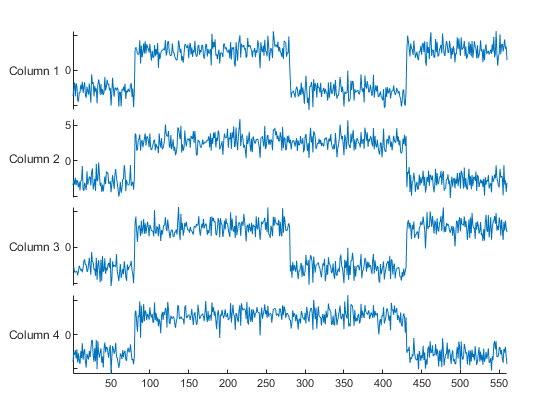

load("kmeansdata.mat")
stackedplot(X);

## Ejercicio 2 - Reducir colores en una imagen

Una imagen a color se compone de 3 canales, Rojo, Verde y Azul (RGB) podemos acomodar cada canal (matriz de MxN) en una sola columna, teniendo así una imagen a color representada solo como un conjunto de dato de 3 dimensiones

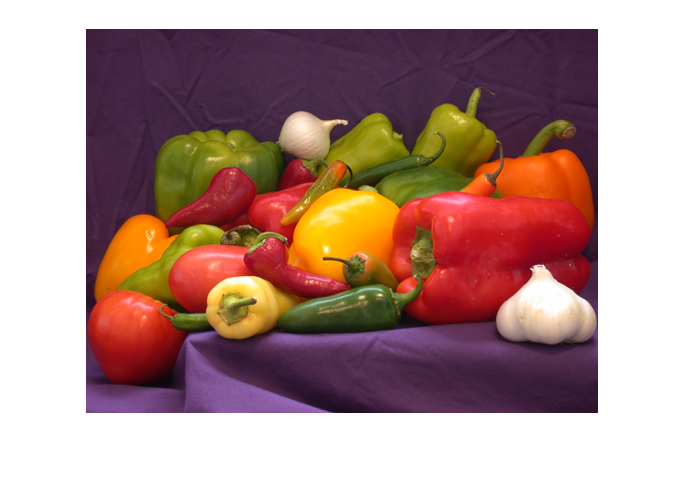

img=im2double(imread("peppers.png"));
imshow(img)

% El proceso de evaluación es costoso si queremos aplicarlo a un dataset de
% mas de medio millons de datos, por lo que vamos a reducir la imagen de
% tamaño 4 veces
% 
img_s = imresize(img,0.25);
[filas, cols, chann]=size(img_s);
% Cada columna de datos es un canal de color
datos = reshape(img_s,filas*cols,3);
% Evaluamos para clusters que vayan de 2 a 10
clustev = evalclusters(datos,"kmeans","silhouette","KList",2:8,"Distance","cosine")

clustev =   SilhouetteEvaluation with properties:

    NumObservations: 12288
         InspectedK: [2 3 4 5 6 7 8]
    CriterionValues: [0.7443 0.8508 0.8102 0.7992 0.7872 0.7754 0.7758]
           OptimalK: 3


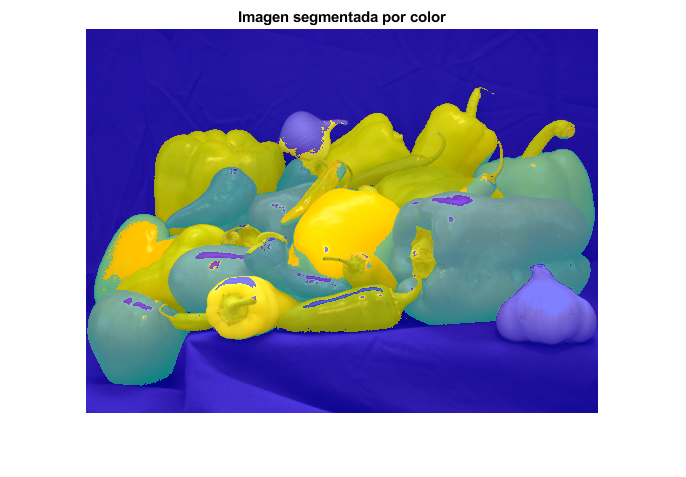


% Determine el valor de clusters para aplicarse en la imagen original
% ¿cuanto debe valer k?
k = clustev.OptimalK;

[nrows,ncols,~] = size(img);
datos_img = reshape(img,nrows*ncols,3);
idx = kmeans(datos_img,k,"Distance","cosine","Replicates",3);
labels = reshape(idx,nrows,ncols);
B = labeloverlay(img,labels); 
imshow(B) 
title('Imagen segmentada por color')

% En la imagen resultante cada color es un cluster o grupo distinto,
% similar a las tablas ahora se puede seleccionar uno solo y procesar por
% separado
